## **Problem 1**

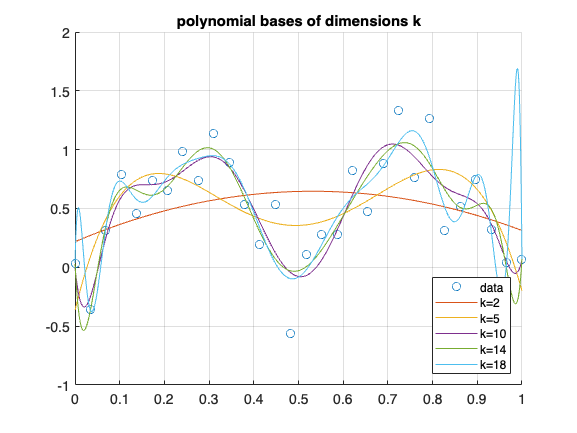

clear;
% variables
t = linspace(0,1,30); 
x = linspace(0,1,1000);
% training data
g_train = sin(2*pi*t).^2 + normrnd(0,sqrt(0.07),[1 30]);
% testing data
g_test = sin(2*pi*x).^2 + normrnd(0,sqrt(0.07),[1 1000]);
% plot the data
figure;
scatter(t,g_train);
grid on;
hold on;

% (a) k = [2 5 10 14 18]
P2 = polyfit(t,g_train,2); 
y2 = polyval(P2,x);
plot(x,y2);
P5 = polyfit(t,g_train,5); 
y5 = polyval(P5,x);
plot(x,y5);
P10 = polyfit(t,g_train,10); 
y10 = polyval(P10,x);
plot(x,y10);
P14 = polyfit(t,g_train,14); 
y14 = polyval(P14,x);
plot(x,y14);
P18 = polyfit(t,g_train,18); 
y18 = polyval(P18,x);
plot(x,y18);
hold off;
title('polynomial bases of dimensions k');
legend('data','k=2','k=5','k=10','k=14','k=18','Location','southeast');

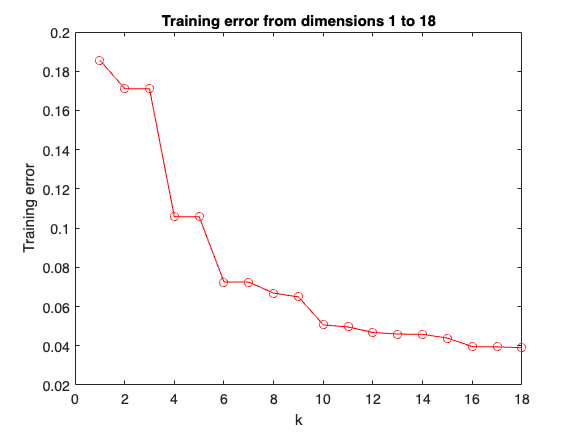

% (b) MSE training error
MSE_Train = zeros(1,18); 
y_train = zeros(18,30);
% calculate training error
for i = 1:18
    y_train(i,:) = polyval(polyfit(t,g_train,i),t);
    MSE_Train(i) = sum((g_train-y_train(i,:)).^2)/30;
end
% plot the data
figure; 
plot(MSE_Train,'o-r'); 
title('Training error from dimensions 1 to 18');
xlabel('k');
ylabel('Training error');

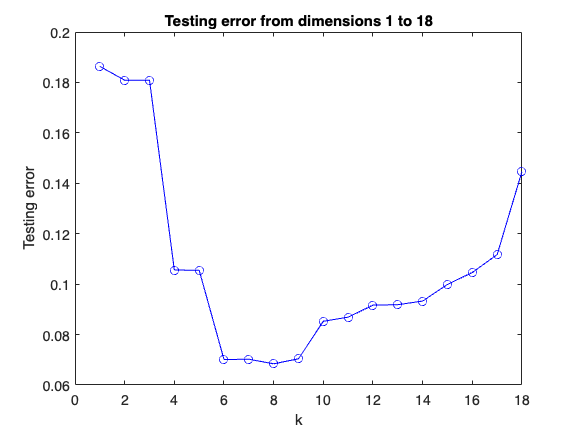

% (c) MSE testing error
MSE_Test = zeros(1,18); 
y_test = zeros(18,1000);
% calculate testing error
for i = 1:18
    y_test(i,:) = polyval(polyfit(t,g_train,i),x);
    MSE_Test(i) = sum((g_test-y_test(i,:)).^2)/1000;
end
% plot the data
figure;
plot(MSE_Test,'o-b');
title('Testing error from dimensions 1 to 18');
xlabel('k');
ylabel('Testing error');

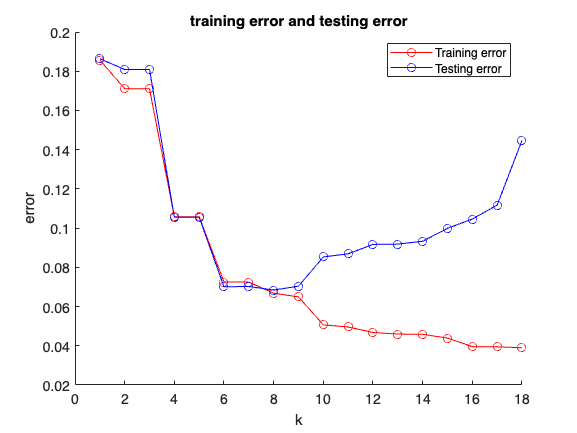

% (d) training error and testing error
figure;
hold on;
plot(MSE_Train,'o-r');
plot(MSE_Test,'o-b');
title('training error and testing error');
xlabel('k');
ylabel('error');
legend('Training error','Testing error');
hold off;

從圖中可以發現，隨著Polynomial dimension(k)增加，

Training error呈現逐漸下降的趨勢，

Testing error在 k = 6 附近時便不再下降，並在高dimensions時error大幅增加。

因此可以推論，在 k = 6 為optimal model complexity，k > 6 開始有overfitting的趨勢，

所以使用6th order在這份資料較佳。

## **Problem 2**

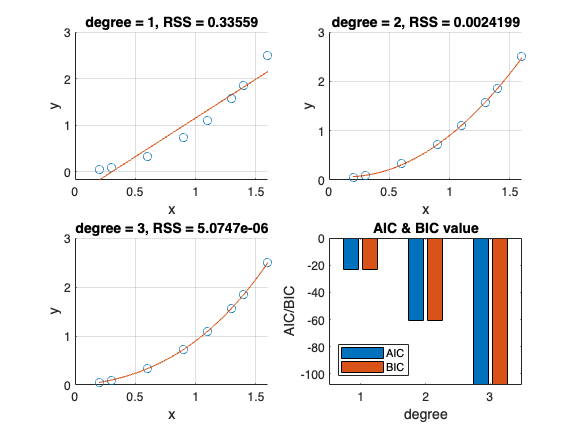

clear;
% Generate data
x = [0.2 0.3 0.6 0.9 1.1 1.3 1.4 1.6];
y = [0.050446 0.098426 0.33277 0.7266 1.0972 1.5697 1.8487 2.5015];
x_ = linspace(0.2,1.6,1000);
y_ = zeros(3,8);
n = length(x);
RSS = zeros(1,3);
AIC = zeros(1,3);
BIC = zeros(1,3);
% degree = 1
P1=polyfit(x,y,1);
y_(1,:) = polyval(P1,x);
RSS(1) = sum((y-y_(1,:)).^2);
AIC(1) = n*log(RSS(1)/n) + 2*1;
BIC(1) = n*log(RSS(1)/n) + log(n)*1;
% degree = 2
P2=polyfit(x,y,2);
y_(2,:) = polyval(P2,x);
RSS(2) = sum((y-y_(2,:)).^2);
AIC(2) = n*log(RSS(2)/n) + 2*2;
BIC(2) = n*log(RSS(2)/n) + log(n)*2;
% degree = 3
P3=polyfit(x,y,3);
y_(3,:) = polyval(P3,x);
RSS(3) = sum((y-y_(3,:)).^2);
AIC(3) = n*log(RSS(3)/n) + 2*3;
BIC(3) = n*log(RSS(3)/n) + log(n)*3;
% plot the model deagee = 1~3
figure;
subplot(2,2,1);
scatter(x,y);
grid on;
hold on; 
plot(x_,polyval(P1,x_)); 
xlabel('x');
ylabel('y');
title(['degree = 1, RSS = ',num2str(RSS(1))]); 
subplot(2,2,2);
scatter(x,y);
grid on;
hold on; 
plot(x_,polyval(P2,x_)); 
xlabel('x');
ylabel('y');
title(['degree = 2, RSS = ',num2str(RSS(2))]); 
subplot(2,2,3);
scatter(x,y);
grid on;
hold on; 
plot(x_,polyval(P3,x_)); 
xlabel('x');
ylabel('y');
title(['degree = 3, RSS = ',num2str(RSS(3))]);
% plot AIC & BIC
subplot(2,2,4);
bar([AIC;BIC]');
legend('AIC','BIC','Location','southwest');
xlabel('degree'); ylabel('AIC/BIC');
title('AIC & BIC value');

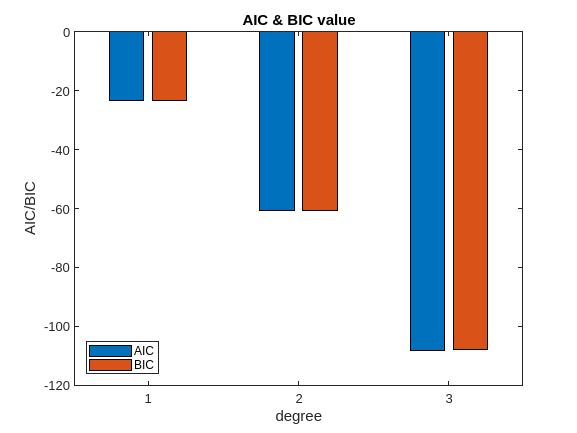

% plot AIC & BIC
figure;
bar([AIC;BIC]');
legend('AIC','BIC','Location','southwest');
xlabel('degree'); ylabel('AIC/BIC');
title('AIC & BIC value');

由AIC/BIC value可知應該選擇degree = 3的model，因為它的AIC/BIC為最小值。

## **Problem 3**